# ドローンのBack-stepping制御に向けた準備

ワークスペース変数のクリア

clear;

## 変換行列の準備

まずはロールピッチヨー角から回転行列を作って、ドローンのボディ座標の単位ベクトルを回転し、慣性座標上で想定通りの姿勢がとられているか確認しましょう。rpy変数で図示する姿勢を変更できます。進行方向がx、zは上下どちらでもよいです。ロールピッチヨー角では、ロールピッチによらず、x-y平面で見た進行方向x軸がヨーで決まるのが特徴です。図は軸の長さが変わってしまってよくわからないので、ボディB座標のx軸を慣性I座標のx-y平面に射影して、x軸との角度を求めてみるとよい (未実装)。

syms phi theta psi real;
Rx = [1, 0, 0;
      0, cos(phi), -sin(phi);
      0, sin(phi), cos(phi)];
Ry = [cos(theta), 0, sin(theta);
      0, 1, 0;
      -sin(theta), 0, cos(theta)];
Rz = [cos(psi), -sin(psi), 0;
      sin(psi), cos(psi), 0;
      0, 0, 1];
R_BtoI = Rz*Ry*Rx;
% R_BtoI = (Rx*Ry*Rz);
R_BtoI

$$R\_BtoI = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

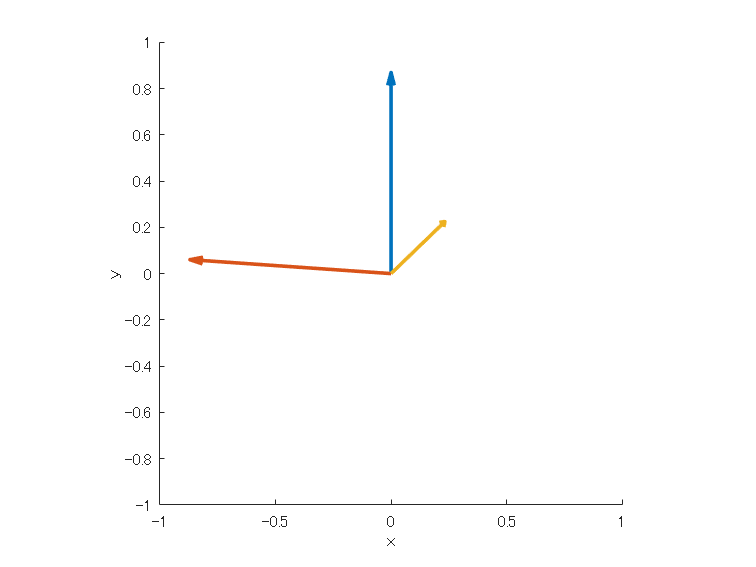

fR_BtoI = matlabFunction(R_BtoI,'Vars',{[phi; theta; psi]});

rpy = [15; 15; 90]*pi/180;

xB_unit = fR_BtoI(rpy)*[1; 0; 0];
yB_unit = fR_BtoI(rpy)*[0; 1; 0];
zB_unit = fR_BtoI(rpy)*[0; 0; 1];
figure(1); clf; hold('on');
xlabel('x'); ylabel('y'); zlabel('z');
% x: blue, y: red, z: yellow
XLine = quiver3(0,0,0,xB_unit(1), xB_unit(2), xB_unit(3));
YLine = quiver3(0,0,0,yB_unit(1), yB_unit(2), yB_unit(3));
ZLine = quiver3(0,0,0,zB_unit(1), zB_unit(2), zB_unit(3));
XLine.LineWidth = 2; YLine.LineWidth = 2; ZLine.LineWidth = 2;
f = gca;
f.XLim = [-1; 1];
f.YLim = [-1; 1];
f.ZLim = [-1; 1];
pbaspect([1 1 1]);

次に角速度の変換を考えましょう。ボディ座標での角速度は、回転行列の時間微分と関係があります。準備として外積を歪対照行列の行列積で考えます。

syms a b c d e f real;
t1 = [a; b; c];
t2 = [d e f];
t3 = cross(t1, t2);
Scew = jacobian(t3, t2);
Scew

$$Scew = \left(\begin{array}{ccc} 0 & -c & b\\ c & 0 & -a\\ -b & a & 0 \end{array}\right)$$

VecToScew = @(x) [0, -x(3), x(2); ...
               x(3), 0, -x(1); ...
              -x(2), x(1), 0];
ScewToVec = @(X) [X(3,2); X(1,3); X(2,1)];

外積の前側を行列に変換、またその逆が得られました。行列の微分を取りたいので関数matDiffをコード末尾に用意しておきます。では角速度を求めます。

syms dphi dtheta dpsi real;
eta = [phi; theta; psi];
deta = [dphi; dtheta; dpsi];
dR = matDiff(R_BtoI, eta, deta);
omega = ScewToVec(R_BtoI'*dR);
P_ItoB = simplify(jacobian(omega, deta));
P_ItoB

$$P\_ItoB = \left(\begin{array}{ccc} 1 & 0 & -\sin\left(\theta \right)\\ 0 & \cos\left(\varphi \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right)\\ 0 & -\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

P_BtoI = simplify(inv(P_ItoB))

$$P\_BtoI = \left(\begin{array}{ccc} 1 & \frac{\sin\left(\varphi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)}\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \frac{\sin\left(\varphi \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right)$$

## 並進運動の制御

詳細は省きます。並進・回転の２つに整理した運動方程式をつくり、並進運動部分からzを抜き出します。


$$\ddot{z} = Rzf/m + g$$



$$\left[\matrix{\ddot{x} \cr \ddot{y}}\right]=R_{xy}f/m$$


R_z, R_{xy}は先の回転行列の右列で、

R_z = R_BtoI(3,3)

$$R\_z = \cos\left(\varphi \right)\,\cos\left(\theta \right)$$

R_xy = R_BtoI(1:2,3)

$$R\_xy = \left(\begin{array}{c} \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) \end{array}\right)$$

です。上式の右辺をu_zと定義します。fが自由に決められるので、u_zも自由に決められます。状態フィードバックなどで作ってください。後で出てくるBack-steppingのためには、この制御器は2階微分可能でないとなりません。普通の状態フィードバックなら可能。u_zが決まれば、それによりfがきまります。


$$u_z := Rzf/m + g$$


次に、x, yの式の右辺もu_x, u_yと定義します。


$$\left[\matrix{u_x \cr u_y}\right] := R_{xy}f/m$$


u_x, u_yはとりあえず制御目標を実現するように決めましょう。これもBack-steppingするなら2階微分可能でないとなりません。そうすると、望ましいu_x, u_yになるような姿勢角phi, thetaを求めることができます。右辺は


$$$\left[\begin{array}{c}
\sin \left(\phi \right)\,\sin \left(\psi \right)+\cos \left(\phi \right)\,\cos \left(\psi \right)\,\sin \left(\theta \right)\\
\cos \left(\phi \right)\,\sin \left(\psi \right)\,\sin \left(\theta \right)-\cos \left(\psi \right)\,\sin \left(\phi \right)\end{array}\right]
\frac{f}{m} = \cos\phi \cos\theta \frac{f}{m}

\left[\begin{array}{c}
\tan\theta\cos\psi + \frac{\tan\phi\sin\psi}{\cos\theta} \\
\tan\theta\sin\psi - \frac{\tan\phi\cos\psi}{\cos\theta}
\end{array}\right]

$$$



$$=
(u_z-g)
\left[\begin{array}{c}
\cos\psi & -\sin\psi \\ \sin\psi & \cos\psi
\end{array}\right]

\left[\begin{array}{c}
\tan\theta \\ -\frac{\tan\phi}{\cos\theta}
\end{array}\right]$$


となります。$u_z-g=\cos\phi \cos\theta \frac{f}{m}$を使いました。

psiの回転行列の逆行列と、u_z-gの逆数を使えば、arctanからtheta=の式が得られ、さらにarctanからphiの式が得られます。理想的なu_x, u_yを実現するphi, thetaをphi_d, theta_dと呼びましょう。後の姿勢制御でそれを実現します。検算しておきます。

syms f real;
syms m positive;
A = cos(phi)*cos(theta)*f/m*...
        [cos(psi), -sin(psi);
         sin(psi), cos(psi)]...
        *[tan(theta); -tan(phi)/cos(theta)];
B = R_xy*f/m;
simplify( A - B )

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

## 回転運動の制御

psiへの目標は別途好きに決定しましょう。psi_dとします。注意すべきは、?_dが時間変化することです。定数目標でないので、それを考慮に入れる必要があります。運動方程式はオイラー角の２階微分として求めます。


$$J_I \ddot{\eta} = P_{BI}\tau + h$$


これを e_eta = eta - eta_dの式に直し、e_eta => 0になるような式を作ればよいです。ただ、姿勢制御が理想的な場合でも指数収束する間はe_etaは0ではなく、あまり性能の良くない制御器になっています。制御器を作るときにLyapunov関数を使いますが、位置 (zeta = [xyzの誤差])制御のLyapunov関数をVzeta =zeta^T * P_zeta * zeta/2、姿勢誤差についてをVeta=eta^T * P_eta * eta/2としてVxyz + Vetaの微分が負になるようなトルク入力tauを決めれば、e_eta=0である必要がなくなり、うまく動くようになります。この時に姿勢制御の誤差が入ってきます。このLyapunov関数は線形システムのものですが、非線形でも使えます。Lyapunov関数、Lyapunov方程式でChatGPTに聞けばいろいろと教えてくれます。というかなんでも教えてくれます。必要なら追加しますが、必要ないことを期待しています。制御の流れの図を添付します。

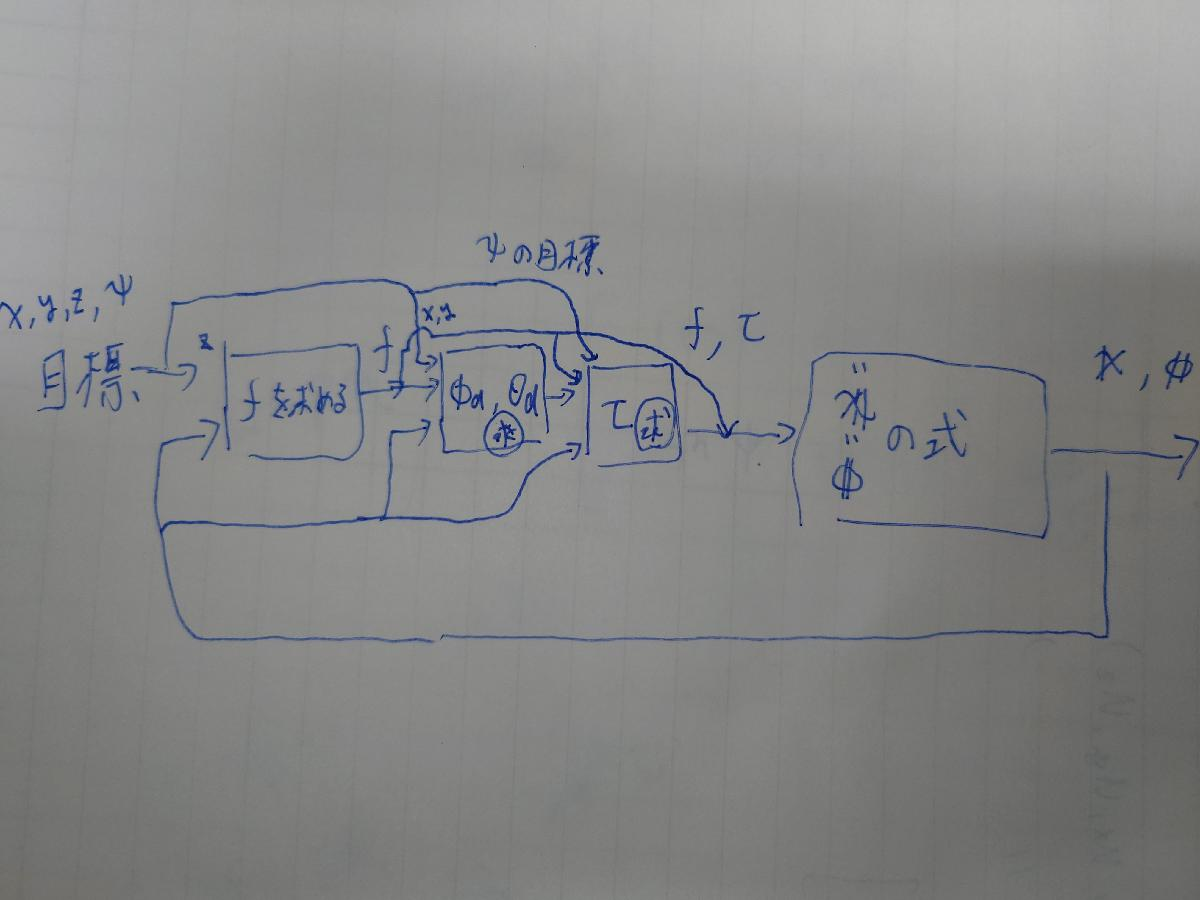

## 上で使う関数

function dM = matDiff(M, x, dx)
    sM = size(M); %row, col
    dM = sym(zeros(sM));
    for ii=1:sM(2)
        dM(:,ii) = simplify(jacobian(M(:,ii), x))*dx;
    end
end